# **EAS 595 Project**

#### Shubham Sharma

Loading the data

clc;
close;
clear;

s = load('data.mat');
F1 = s.F1;
F2 = s.F2;
testf1 = F1(101:1000,:);
testf2 = F2(101:1000,:);

Step 1.Training: Calculating mean and variance for F1 and F2

f1mean(1,1,1:5) = mean(s.F1(1:100,:), 1);
f2mean(1,1,1:5) = mean(s.F2(1:100,:), 1);
f1var(1,1,1:5) = var(s.F1(1:100,:), 1);
f2var(1,1,1:5) = var(s.F2(1:100,:), 1);

Step 2.1: Testing: F1 and F2

% norm = @(x,mean,var) ((1/(sqrt(2*pi)*sqrt(var))) .* (exp(-(x - (mean)).^2)./ (2*(var))));
PCF1 = normpdf(testf1,f1mean,sqrt(f1var));
PCF2 = normpdf(testf2,f2mean,sqrt(f2var));
[argvalue_F1,argmax_F1] = max(PCF1,[],3);
[argvalue_F2,argmax_F2] = max(PCF2,[],3);

Step 2.2: Accuracy

acc_f1 = (sum(sum(argmax_F1 == [1 2 3 4 5]))/numel(argmax_F1)) * 100;
err_rate_f1 = 100 - acc_f1;

Step 3: Standard Normal

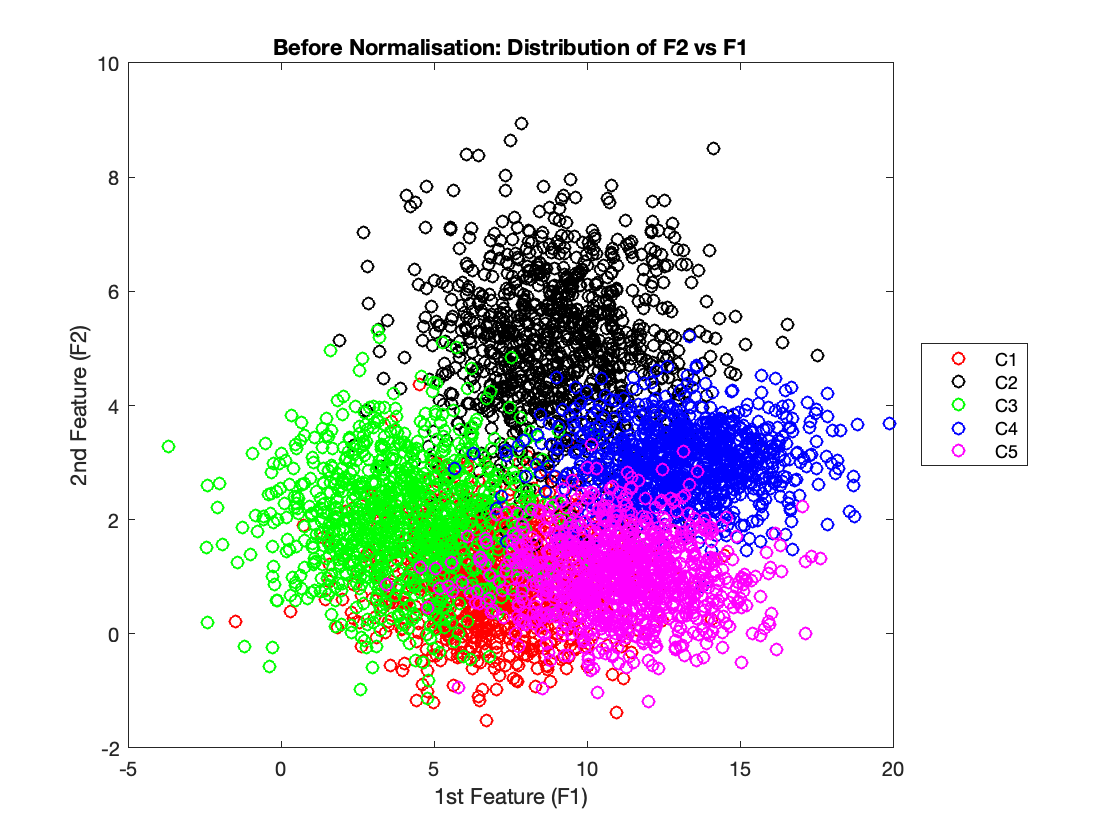

Z1 = (F1 - mean(F1,2))./(sqrt(var(F1,0,2)));

figure
fig = plot(F1,F2,'o');
xlabel('1st Feature (F1)');
ylabel('2nd Feature (F2)');
title('Before Normalisation: Distribution of F2 vs F1');
legend('C1','C2','C3','C4','C5','Location','eastoutside')
set(fig, {'color'}, {'r';'k';'g';'b';'m'});

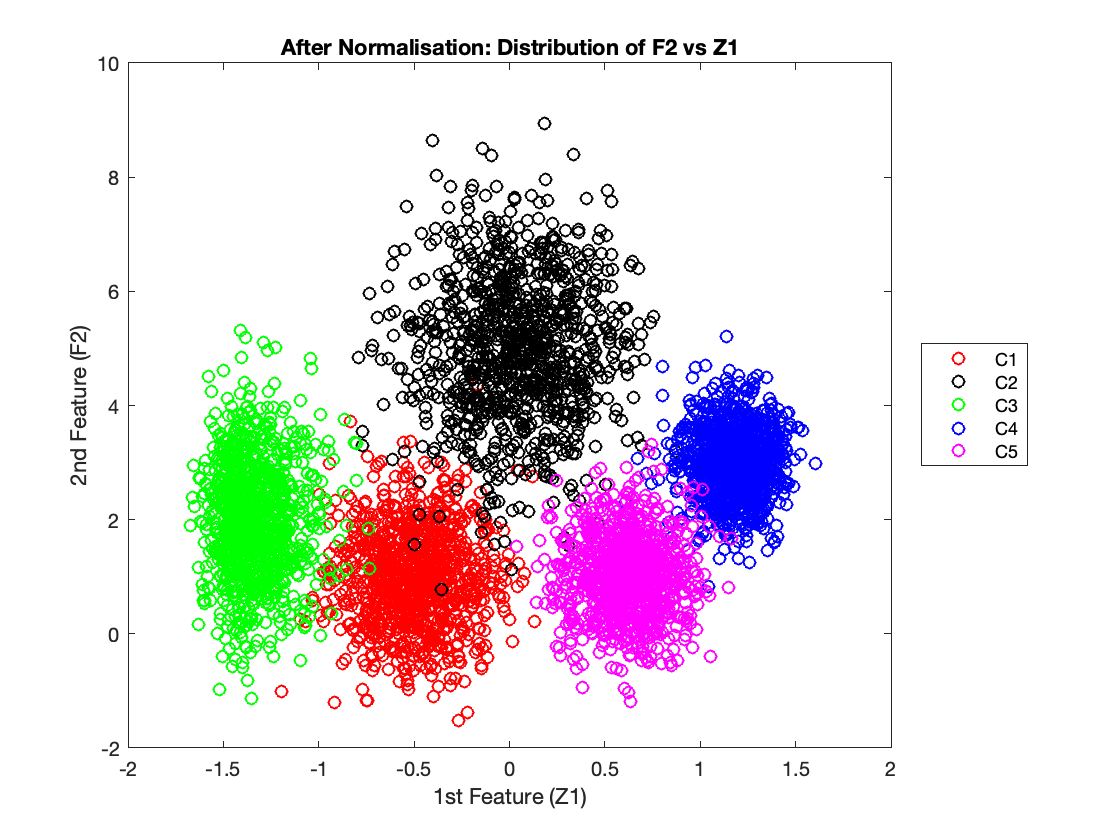


figure
fig = plot(Z1,F2,'o');
xlabel('1st Feature (Z1)');
ylabel('2nd Feature (F2)');
title('After Normalisation: Distribution of F2 vs Z1');
legend('C1','C2','C3','C4','C5','Location','eastoutside')
set(fig, {'color'}, {'r';'k';'g';'b';'m'});

 Step 4: 

**Case 2: X = Z1**

Training

z1mean(1,1,1:5) = mean(Z1(1:100,:), 1);
z1var(1,1,1:5) = var(Z1(1:100,:), 1);

Testing

testz1 = Z1(101:1000,:);
PCZ1 = normpdf(testz1,z1mean,sqrt(z1var));
[argvalue_Z1,argmax_Z1] = max(PCZ1,[],3);

Accuracy

acc_z1 = (sum(sum(argmax_Z1 == [1 2 3 4 5]))/numel(argmax_Z1)) * 100;
err_rate_z1 = 100 - acc_z1; 

**Case 2: X = F2**

Accuracy

acc_f2 = (sum(sum(argmax_F2 == [1 2 3 4 5]))/numel(argmax_F2)) * 100;
err_rate_f2 = 100 - acc_f2;

**Case 3: X = [Z1; F2] **

The resulting conditional probabilities for the multivariate distribution would simply be the product of the conditional probabilities for Z1 and F2 since these are independent.

PCXV = PCZ1.*PCF2;
[argvalue_XV,argmax_XV] = max(PCXV,[],3);
acc_xv = (sum(sum(argmax_XV == [1 2 3 4 5]))/numel(argmax_XV)) * 100;
err_rate_xv = 100 - acc_xv;
x = 0:.1:1;
y = [x; exp(x)];

fprintf('Accuracy for F1: %f %%', acc_f1);

Accuracy for F1: 53.000000 %

fprintf('Accuracy for F2: %f %%', acc_f2);

Accuracy for F2: 55.155556 %

fprintf('Accuracy for Z1 (Normalised F1): %f %%', acc_z1);

Accuracy for Z1 (Normalised F1): 88.333333 %

fprintf('Accuracy for X = [Z1; F2] (multivariate distribution): %f %%', acc_xv);

Accuracy for X = [Z1; F2] (multivariate distribution): 97.977778 %

fprintf('\n');

fprintf('Error Rate for F1: %f %%', err_rate_f1);

Error Rate for F1: 47.000000 %

fprintf('Error Rate for F2: %f %%', err_rate_f2);

Error Rate for F2: 44.844444 %

fprintf('Error Rate for Z1(Normalised F1): %f %%', err_rate_z1);

Error Rate for Z1(Normalised F1): 11.666667 %

fprintf('Error Rate for X = [Z1; F2] (multivariate distribution): %f %%', err_rate_xv);

Error Rate for X = [Z1; F2] (multivariate distribution): 2.022222 %

fprintf('\n');

fprintf('The number of instances correctly classified for F1 (classwise): ');

The number of instances correctly classified for F1 (classwise): 

display((sum(argmax_F1 == [1 2 3 4 5])));

   432   262   691   596   404



fprintf('The number of instances correctly classified for F2 (classwise): ');

The number of instances correctly classified for F2 (classwise): 

display((sum(argmax_F2 == [1 2 3 4 5])));

   212   750   242   699   579



fprintf('The number of instances correctly classified for Z1 (classwise): ');

The number of instances correctly classified for Z1 (classwise): 

display((sum(argmax_Z1 == [1 2 3 4 5])));

   763   658   887   868   799



fprintf('The number of instances correctly classified for X = [Z1; F2] (multivariate distribution) (classwise): ');

The number of instances correctly classified for X = [Z1; F2] (multivariate distribution) (classwise): 

display((sum(argmax_XV == [1 2 3 4 5])));

   878   876   889   884   882

